# Figure 2 UMAP projections

Code for UMAP projections in Figure 2B, supplementary figure 13B (female group1)

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'BatID')
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood');
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4','MPSmicReduction4Clustering') % obtained from DeafBats_CatCalls8bis.mlx

MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

Get color vectors ready

% Get the color vector ready for BatName, Sex and Deafness
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
GGPath = dir('/Users/elie/Google Drive*');
try
    Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
    [~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
catch ME
    Path2Paper = fullfile(GGPath.folder, GGPath.name, 'Mon Drive', 'BatmanData', 'Deaf Paper');
    Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'Mon Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
    [~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
end

BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end
    
end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

calculate the PCA of the microphone MPS for plotting purposes

% Loading previous data
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'),'MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')

%% Restrict the MPS spectral frequency to 3 cycles/kHz and normalized all
% MPS
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';

% calculate the PCA on MPS
[PC,Score,~, ~, VarExpl,~] = pca(MPS_mic_norm);
NPC90var = find(cumsum(VarExpl)>90,1);
save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'Score', 'PC','VarExpl')
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'Score', 'PC','VarExpl')
Score_trim = Score(:,1:100);
clear Score


figure()
plot(cumsum(VarExpl))
title('cumulative sum of variance explained')
xlabel('# PCs')
ylabel('Percentage')

figure()
plot(VarExpl)
title('Percent variance explained by each PC')
xlabel('# PCs')
ylabel('Percentage')

NPC1perc = find(VarExpl<1,1)-1;
fprintf(1,'%d PCs explain at least 1%% of the variance in the data',NPC1perc)

5 PCs explain at least 1% of the variance in the data

Get the distance of each call from all individuals to the closest set of 10 calls from an opposite treatment bat from the same sex

NumCalls=10;
KSDistanceAll_5PC = cell(sum(MicAudioGood01),1);
KSDistanceAll_10PC = cell(sum(MicAudioGood01),1);
KSDistanceAll_50PC = cell(sum(MicAudioGood01),1);
SexDeaf_mic = SexDeaf(MicAudioGood01);

BatID_mic = str2double(BatID(MicAudioGood01));
BatID_Pair_KSDistanceAll_5PC = cell(sum(MicAudioGood01),1);
BatID_Pair_KSDistanceAll_10PC = cell(sum(MicAudioGood01),1);
BatID_Pair_KSDistanceAll_50PC = cell(sum(MicAudioGood01),1);
DiffNeigh = 0;
parfor vv=1:sum(MicAudioGood01)
    if rem(vv,1000)==0
        fprintf(1, 'Voc %d/%d\n', vv,sum(MicAudioGood01))
    end
    BatID_local = BatID_mic(vv);
    SexDeaf_local = SexDeaf_mic{vv};
    % opposite treatment same sex targets
    BatID_targets = BatName(logical((~contains(BatSexDeaf, SexDeaf_local(1))).*contains(BatSexDeaf, SexDeaf_local(2))));
    % loop through targets and calculate distance to 10 closest calls
    Targets_dist_5PC = nan(size(BatID_targets));
    Targets_dist_10PC = nan(size(BatID_targets));
    Targets_dist_50PC = nan(size(BatID_targets));
    for tt=1:length(BatID_targets)
        Score_local = Score_trim(vv,:);
        Score_targets = Score_trim(BatID_mic==BatID_targets(tt),:);
        Dist_targets_5PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_10PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_50PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        for ttvv=1:sum(BatID_mic==BatID_targets(tt))
            Dist_targets_5PC(ttvv) = sum((Score_local(1:5) - Score_targets(ttvv,1:5)).^2).^0.5;
            Dist_targets_10PC(ttvv) = sum((Score_local(1:10) - Score_targets(ttvv,1:10)).^2).^0.5;
            Dist_targets_50PC(ttvv) = sum((Score_local(1:50) - Score_targets(ttvv,1:50)).^2).^0.5;
        end
        Dist_targets_5PC = sort(Dist_targets_5PC, 'ascend');
        Targets_dist_5PC(tt) = mean(Dist_targets_5PC(1:NumCalls));
        Dist_targets_10PC = sort(Dist_targets_10PC, 'ascend');
        Targets_dist_10PC(tt) = mean(Dist_targets_10PC(1:NumCalls));
        Dist_targets_50PC = sort(Dist_targets_50PC, 'ascend');
        Targets_dist_50PC(tt) = mean(Dist_targets_50PC(1:NumCalls));
    end
    [KSDistanceAll_5PC{vv}, I_5PC] = min(Targets_dist_5PC);
    [KSDistanceAll_10PC{vv}, I_10PC] = min(Targets_dist_10PC);
    [KSDistanceAll_50PC{vv}, I_50PC] = min(Targets_dist_50PC);
    if I_5PC~=I_10PC || I_5PC~=I_50PC || I_10PC~=I_50PC
        DiffNeigh = DiffNeigh +1;
    end
    BatPair = sort([BatID_local BatID_targets(I_5PC)]);
    BatID_Pair_KSDistanceAll_5PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_10PC)]);
    BatID_Pair_KSDistanceAll_10PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_50PC)]);
    BatID_Pair_KSDistanceAll_50PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
end

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 4).
Voc 1000/28091
Voc 8000/28091
Voc 11000/28091
Voc 14000/28091
Voc 4000/28091
Voc 7000/28091
Voc 10000/28091
Voc 6000/28091
Voc 3000/28091
Voc 13000/28091
Voc 9000/28091
Voc 5000/28091
Voc 12000/28091
Voc 2000/28091
Voc 16000/28091
Voc 21000/28091
Voc 18000/28091
Voc 19000/28091
Voc 15000/28091
Voc 17000/28091
Voc 20000/28091
Voc 22000/28091
Voc 23000/28091
Voc 25000/28091
Voc 26000/28091
Voc 24000/28091
Voc 27000/28091
Voc 28000/28091


KSDistanceAll_5PC = cell2mat(KSDistanceAll_5PC);
KSDistanceAll_10PC = cell2mat(KSDistanceAll_10PC);
KSDistanceAll_50PC = cell2mat(KSDistanceAll_50PC);
fprintf(1,'%d/%d vocalizations found a different closest neighbor according to the different distance metrics\n', DiffNeigh, sum(MicAudioGood))

9492/28091 vocalizations found a different closest neighbor according to the different distance metrics


save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'KSDistanceAll_5PC','KSDistanceAll_10PC','KSDistanceAll_50PC','BatID_Pair_KSDistanceAll_5PC','BatID_Pair_KSDistanceAll_10PC','BatID_Pair_KSDistanceAll_50PC','-append')
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'KSDistanceAll_5PC','KSDistanceAll_10PC','KSDistanceAll_50PC','BatID_Pair_KSDistanceAll_5PC','BatID_Pair_KSDistanceAll_10PC','BatID_Pair_KSDistanceAll_50PC', '-append')

Get the Null KS distance of each call from all individuals to the closest set of 10 calls from any treatment bat from the same sex

NumCalls=10;
NullKSDistanceAll_5PC = cell(sum(MicAudioGood01),1);
NullKSDistanceAll_10PC = cell(sum(MicAudioGood01),1);
NullKSDistanceAll_50PC = cell(sum(MicAudioGood01),1);
SexDeaf_mic = SexDeaf(MicAudioGood01);

BatID_mic = str2double(BatID(MicAudioGood01));
BatID_Pair_NullKSDistanceAll_5PC = cell(sum(MicAudioGood01),1);
BatID_Pair_NullKSDistanceAll_10PC = cell(sum(MicAudioGood01),1);
BatID_Pair_NullKSDistanceAll_50PC = cell(sum(MicAudioGood01),1);
DiffNeigh = 0;
parfor vv=1:sum(MicAudioGood01)
    if rem(vv,1000)==0
        fprintf(1, 'Voc %d/%d\n', vv,sum(MicAudioGood01))
    end
    BatID_local = BatID_mic(vv);
    SexDeaf_local = SexDeaf_mic{vv};
    % any treatment same sex targets (estimate the local density for each
    % sex)
%     BatID_targets = BatName(logical((contains(BatSexDeaf, SexDeaf_local(1))).*contains(BatSexDeaf, SexDeaf_local(2))));
    BatID_targets = BatName(contains(BatSexDeaf, SexDeaf_local(2)));
    % loop through targets and calculate distance to 10 closest calls
    Targets_dist_5PC = nan(size(BatID_targets));
    Targets_dist_10PC = nan(size(BatID_targets));
    Targets_dist_50PC = nan(size(BatID_targets));
    for tt=1:length(BatID_targets)
        Score_local = Score_trim(vv,:);
        Score_targets = Score_trim(BatID_mic==BatID_targets(tt),:);
        Dist_targets_5PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_10PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_50PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        for ttvv=1:sum(BatID_mic==BatID_targets(tt))
            Dist_targets_5PC(ttvv) = sum((Score_local(1:5) - Score_targets(ttvv,1:5)).^2).^0.5;
            Dist_targets_10PC(ttvv) = sum((Score_local(1:10) - Score_targets(ttvv,1:10)).^2).^0.5;
            Dist_targets_50PC(ttvv) = sum((Score_local(1:50) - Score_targets(ttvv,1:50)).^2).^0.5;
        end
        Dist_targets_5PC = sort(Dist_targets_5PC, 'ascend');
        Targets_dist_5PC(tt) = mean(Dist_targets_5PC(1:NumCalls));
        Dist_targets_10PC = sort(Dist_targets_10PC, 'ascend');
        Targets_dist_10PC(tt) = mean(Dist_targets_10PC(1:NumCalls));
        Dist_targets_50PC = sort(Dist_targets_50PC, 'ascend');
        Targets_dist_50PC(tt) = mean(Dist_targets_50PC(1:NumCalls));
    end
    [NullKSDistanceAll_5PC{vv}, I_5PC] = min(Targets_dist_5PC);
    [NullKSDistanceAll_10PC{vv}, I_10PC] = min(Targets_dist_10PC);
    [NullKSDistanceAll_50PC{vv}, I_50PC] = min(Targets_dist_50PC);
    if I_5PC~=I_10PC || I_5PC~=I_50PC || I_10PC~=I_50PC
        DiffNeigh = DiffNeigh +1;
    end
    BatPair = sort([BatID_local BatID_targets(I_5PC)]);
    BatID_Pair_NullKSDistanceAll_5PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_10PC)]);
    BatID_Pair_NullKSDistanceAll_10PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_50PC)]);
    BatID_Pair_NullKSDistanceAll_50PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
end

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 4).
Voc 1000/28091
Voc 8000/28091
Voc 11000/28091
Voc 14000/28091
Voc 4000/28091
Voc 7000/28091
Voc 10000/28091
Voc 13000/28091
Voc 3000/28091
Voc 6000/28091
Voc 9000/28091
Voc 12000/28091
Voc 2000/28091
Voc 5000/28091
Voc 18000/28091
Voc 16000/28091
Voc 21000/28091
Voc 19000/28091
Voc 17000/28091
Voc 15000/28091
Voc 20000/28091
Voc 23000/28091
Voc 22000/28091
Voc 24000/28091
Voc 26000/28091
Voc 25000/28091
Voc 27000/28091
Voc 28000/28091


NullKSDistanceAll_5PC = cell2mat(NullKSDistanceAll_5PC);
NullKSDistanceAll_10PC = cell2mat(NullKSDistanceAll_10PC);
NullKSDistanceAll_50PC = cell2mat(NullKSDistanceAll_50PC);
fprintf(1,'%d/%d vocalizations found a different closest neighbor according to the different distance metrics\n', DiffNeigh, sum(MicAudioGood))

11036/28091 vocalizations found a different closest neighbor according to the different distance metrics


save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'NullKSDistanceAll_5PC','NullKSDistanceAll_10PC','NullKSDistanceAll_50PC','BatID_Pair_NullKSDistanceAll_5PC','BatID_Pair_NullKSDistanceAll_10PC','BatID_Pair_NullKSDistanceAll_50PC','-append')
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'NullKSDistanceAll_5PC','NullKSDistanceAll_10PC','NullKSDistanceAll_50PC','BatID_Pair_NullKSDistanceAll_5PC','BatID_Pair_NullKSDistanceAll_10PC','BatID_Pair_NullKSDistanceAll_50PC', '-append')

Get the distance of each call emitted by all individuals to the closest set of 10 calls from an opposite sex individual

NumCalls=10;
% Mic_hearing_01 = logical(MicAudioGood01 .* contains(SexDeaf,'H'));
SexDistance_5PC = cell(sum(MicAudioGood01),1);
SexDistance_10PC = cell(sum(MicAudioGood01),1);
SexDistance_50PC = cell(sum(MicAudioGood01),1);
Sex_mic = Sex(MicAudioGood01);
BatID_mic = str2double(BatID(MicAudioGood01));
BatID_Pair_SexDistance_5PC = cell(sum(MicAudioGood01),1);
BatID_Pair_SexDistance_10PC = cell(sum(MicAudioGood01),1);
BatID_Pair_SexDistance_50PC = cell(sum(MicAudioGood01),1);
% Score_trim_hearing = Score_trim(contains(SexDeaf(MicAudioGood01), 'H'),:);
DiffNeigh = 0;
parfor vv=1:sum(MicAudioGood01)
    if rem(vv,1000)==0
        fprintf(1, 'Voc %d/%d\n', vv,sum(MicAudioGood01))
    end
    BatID_local = BatID_mic(vv);
    Sex_local = Sex_mic{vv};
    % opposite sex targets
    BatID_targets = BatName(~contains(BatSexDeaf, Sex_local));
    % loop through targets and calculate distance to 10 closest calls
    Targets_dist_5PC = nan(size(BatID_targets));
    Targets_dist_10PC = nan(size(BatID_targets));
    Targets_dist_50PC = nan(size(BatID_targets));
    for tt=1:length(BatID_targets)
        Score_local = Score_trim(vv, 1:100);
        Score_targets = Score_trim(BatID_mic==BatID_targets(tt),1:100);
        Dist_targets_5PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_10PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        Dist_targets_50PC = nan(1, sum(BatID_mic==BatID_targets(tt)));
        for ttvv=1:sum(BatID_mic==BatID_targets(tt))
            Dist_targets_5PC(ttvv) = sum((Score_local(1:5) - Score_targets(ttvv,1:5)).^2).^0.5;
            Dist_targets_10PC(ttvv) = sum((Score_local(1:10) - Score_targets(ttvv,1:10)).^2).^0.5;
            Dist_targets_50PC(ttvv) = sum((Score_local(1:50) - Score_targets(ttvv,1:50)).^2).^0.5;
        end
        Dist_targets_5PC = sort(Dist_targets_5PC, 'ascend');
        Dist_targets_10PC = sort(Dist_targets_10PC, 'ascend');
        Dist_targets_50PC = sort(Dist_targets_50PC, 'ascend');
        Targets_dist_5PC(tt) = mean(Dist_targets_5PC(1:NumCalls));
        Targets_dist_10PC(tt) = mean(Dist_targets_10PC(1:NumCalls));
        Targets_dist_50PC(tt) = mean(Dist_targets_50PC(1:NumCalls));
    end
    [SexDistance_5PC{vv}, I_5PC] = min(Targets_dist_5PC);
    [SexDistance_10PC{vv}, I_10PC] = min(Targets_dist_10PC);
    [SexDistance_50PC{vv}, I_50PC] = min(Targets_dist_50PC);
    if I_5PC~=I_10PC || I_5PC~=I_50PC || I_10PC~=I_50PC
        DiffNeigh = DiffNeigh +1;
    end
    BatPair = sort([BatID_local BatID_targets(I_5PC)]);
    BatID_Pair_SexDistance_5PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_10PC)]);
    BatID_Pair_SexDistance_10PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
    BatPair = sort([BatID_local BatID_targets(I_50PC)]);
    BatID_Pair_SexDistance_50PC{vv} = [num2str(BatPair(1)) num2str(BatPair(2))];
end

Voc 1000/28091
Voc 8000/28091
Voc 11000/28091
Voc 4000/28091
Voc 14000/28091
Voc 7000/28091
Voc 10000/28091
Voc 3000/28091
Voc 13000/28091
Voc 6000/28091
Voc 9000/28091
Voc 2000/28091
Voc 12000/28091
Voc 5000/28091
Voc 18000/28091
Voc 16000/28091
Voc 21000/28091
Voc 19000/28091
Voc 17000/28091
Voc 15000/28091
Voc 20000/28091
Voc 23000/28091
Voc 22000/28091
Voc 26000/28091
Voc 25000/28091
Voc 24000/28091
Voc 27000/28091
Voc 28000/28091


SexDistance_5PC = cell2mat(SexDistance_5PC);
SexDistance_10PC = cell2mat(SexDistance_10PC);
SexDistance_50PC = cell2mat(SexDistance_50PC);
fprintf(1,'%d/%d vocalizations found a different closest neighbor according to the different distance metrics\n', DiffNeigh, sum(MicAudioGood))

16426/28091 vocalizations found a different closest neighbor according to the different distance metrics


save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'SexDistance_5PC', 'SexDistance_10PC','SexDistance_50PC', 'BatID_Pair_SexDistance_5PC','BatID_Pair_SexDistance_10PC','BatID_Pair_SexDistance_50PC', '-append')
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'SexDistance_5PC','SexDistance_10PC','SexDistance_50PC', 'BatID_Pair_SexDistance_5PC','BatID_Pair_SexDistance_10PC','BatID_Pair_SexDistance_50PC', '-append')

Calculate the distance to the 10 closest calls to then correct the distances calculated by the distance expected given density of points

NumCalls=10;
NullDistanceAll_5PC = cell(sum(MicAudioGood01),1);
NullDistanceAll_10PC = cell(sum(MicAudioGood01),1);
NullDistanceAll_50PC = cell(sum(MicAudioGood01),1);
parfor vv=1:sum(MicAudioGood01)
    if rem(vv,1000)==0
        fprintf(1, 'Voc %d/%d\n', vv,sum(MicAudioGood01))
    end
    Score_local = Score_trim(vv, :);
    NullDistance_5PC_All = nan(sum(MicAudioGood01),1);
    NullDistance_10PC_All  = nan(sum(MicAudioGood01),1);
    NullDistance_50PC_All = nan(sum(MicAudioGood01),1);
    for vv2=1:sum(MicAudioGood01)
        Score_target = Score_trim(vv2,:);
        NullDistance_5PC_All(vv2) = sum((Score_local(1:5) - Score_target(1:5)).^2).^0.5;
        NullDistance_10PC_All(vv2) = sum((Score_local(1:10) - Score_target(1:10)).^2).^0.5;
        NullDistance_50PC_All(vv2) = sum((Score_local(1:50) - Score_target(1:50)).^2).^0.5;
    end
    % remove the Distance to itself
    NullDistance_5PC_All(NullDistance_5PC_All==0)=[];
    NullDistance_10PC_All(NullDistance_10PC_All==0)=[];
    NullDistance_50PC_All(NullDistance_50PC_All==0)=[];
    % get the mean distance to the 10 closest calls
    D_local = sort(NullDistance_5PC_All, 'ascend');
    NullDistanceAll_5PC{vv} = mean(D_local(1:10));
    D_local = sort(NullDistance_10PC_All, 'ascend');
    NullDistanceAll_10PC{vv} = mean(D_local(1:10));
    D_local = sort(NullDistance_50PC_All, 'ascend');
    NullDistanceAll_50PC{vv} = mean(D_local(1:10));
end

Voc 1000/28091
Voc 8000/28091
Voc 11000/28091
Voc 4000/28091
Voc 14000/28091
Voc 7000/28091
Voc 10000/28091
Voc 13000/28091
Voc 3000/28091
Voc 6000/28091
Voc 9000/28091
Voc 12000/28091
Voc 2000/28091
Voc 5000/28091
Voc 18000/28091
Voc 16000/28091
Voc 21000/28091
Voc 19000/28091
Voc 17000/28091
Voc 15000/28091
Voc 20000/28091
Voc 23000/28091
Voc 22000/28091
Voc 24000/28091
Voc 26000/28091
Voc 25000/28091
Voc 27000/28091
Voc 28000/28091


NullDistanceAll_5PC = [NullDistanceAll_5PC{:}]';
NullDistanceAll_10PC = [NullDistanceAll_10PC{:}]';
NullDistanceAll_50PC = [NullDistanceAll_50PC{:}]';
save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'NullDistanceAll_5PC','NullDistanceAll_10PC','NullDistanceAll_50PC','-append')
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'NullDistanceAll_5PC','NullDistanceAll_10PC','NullDistanceAll_50PC', '-append')

Loading previous data

% load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'BatID')
% load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood');
% load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCallsUMAPMic.mat'), 'MPSmicReduction4Clustering') % obtained from DeafBats_CatCalls8bis.mlx
% load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'), 'KSDistanceAll_5PC','KSDistanceAll_10PC','KSDistanceAll_50PC','BatID_Pair_KSDistanceAll_5PC','BatID_Pair_KSDistanceAll_10PC','BatID_Pair_KSDistanceAll_50PC')
% load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_SexDimorph.mat'),
% 'NullDistanceAll_5PC','NullDistanceAll_10PC','NullDistanceAll_50PC');
% MicAudioGood01 = MicAudioGood;
% MicAudioGood01(isnan(MicAudioGood01)) = 0;
% MicAudioGood01 = logical(MicAudioGood01);


Plot the UMAP projections with color coded the distance to the closest opposite sex individual calls (distance in the PCA space corrected for point density)

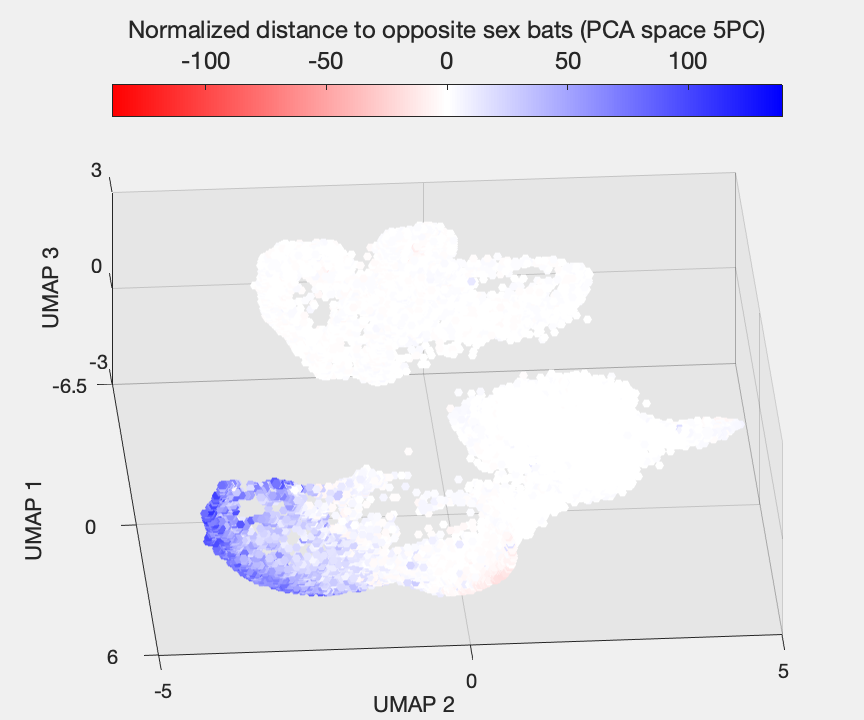

Sex_mic_sign = 2.*contains(Sex_mic, 'M') -1;
Fig15 = figure(15);
clf
set(gcf,'Visible','on')
Tbl = table(MPSmicReduction4Clustering(:,1),MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),(SexDistance_5PC-NullDistanceAll_5PC).*Sex_mic_sign,SexDistance_5PC-NullDistanceAll_5PC,Sex_mic_sign, 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','SexDistanceNP','SexDistance', 'Sex'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','SexDistanceNP', 'SizeData',20);
% SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'AlphaVariable','SexDistance','ColorVariable','Sex', 'SizeData',20);
% SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'AlphaVariable','SexDistance', 'SizeData',20);
xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
Cmap = [ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
% colormap(GRAD)
cc.Label.String = 'Normalized distance to opposite sex bats (PCA space 5PC)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

XLim = [-6.5 6];
set(gca, 'XLim', XLim);
YLim = [-5 5];
set(gca, 'YLim', YLim);
ZLim = [-3 3];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
set(gca,'color',[0.9 0.9 0.9])
Fig15.Units = 'inches';
Fig15.Position(3:4) = [6 5];
Fig15.PaperSize = [6 5];
exportgraphics(Fig15,fullfile(Path2Paper,'SupFigure3_UMAP_MFNormDistance_PCA.pdf'),'resolution', 600)

Plot the UMAP projections with color coded the distance to the closest opposite treatment but same sex individual calls for All male bats (distance in the PCA space)

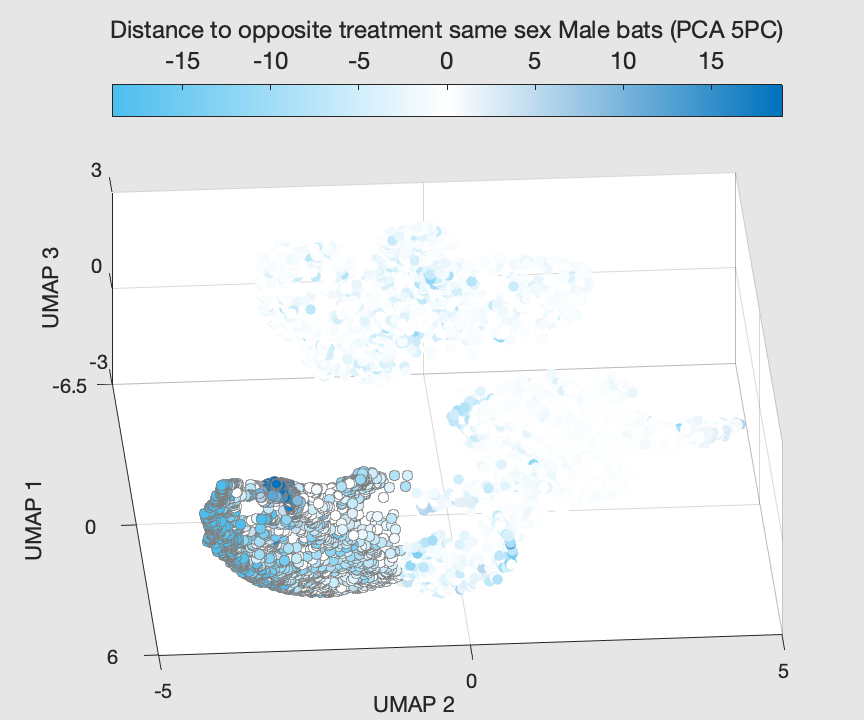

Mic_male_01 = logical(MicAudioGood01 .* contains(SexDeaf,'M'));
SexDeaf_mic = SexDeaf(MicAudioGood01);
SexDeaf_mic_males = SexDeaf(Mic_male_01 );
KSM_mic_sign = 2.*contains(SexDeaf_mic_males, 'D') -1;
NormDist = KSDistanceAll_5PC(contains(SexDeaf_mic, 'M')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'M'));
Fig13 = figure(13);
clf
set(gcf,'Visible','on')
Clustno4HM_logical = logical(contains(SexDeaf(MicAudioGood01), 'M') .* (TmicAll4~=4));
Tbl = table(MPSmicReduction4Clustering(Clustno4HM_logical,1),MPSmicReduction4Clustering(Clustno4HM_logical,2),MPSmicReduction4Clustering(Clustno4HM_logical,3),NormDist(TmicAll4(contains(SexDeaf_mic, 'M'))~=4).*KSM_mic_sign(TmicAll4(contains(SexDeaf_mic, 'M'))~=4), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30);
hold on
Clust4HM_logical = logical(contains(SexDeaf(MicAudioGood01), 'M') .* (TmicAll4==4));
Tbl = table(MPSmicReduction4Clustering(Clust4HM_logical,1),MPSmicReduction4Clustering(Clust4HM_logical,2),MPSmicReduction4Clustering(Clust4HM_logical,3),NormDist(TmicAll4(contains(SexDeaf_mic, 'M'))==4).*KSM_mic_sign(TmicAll4(contains(SexDeaf_mic, 'M'))==4), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30,'MarkerEdgeColor',[0.5 0.5 0.5]);

xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
ColR = UCSexDeaf(1,:); % Color for Deaf males
ColL = UCSexDeaf(2,:);% Color for hearing males
Cmap = [(ColL(1):(1-ColL(1))/127:1)' (ColL(2):(1-ColL(2))/127:1)' (ColL(3):(1-ColL(3))/127:1)';
flip(ColR(1):(1-ColR(1))/127:1)' flip(ColR(2):(1-ColR(2))/127:1)' flip(ColR(3):(1-ColR(3))/127:1)'];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
[H, E]=histcounts(NormDist, 'Normalization', 'cdf');
CLim = E(find(H>0.95,1,"first"));
caxis([-CLim CLim])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment same sex Male bats (PCA 5PC)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

XLim = [-6.5 6];
set(gca, 'XLim', XLim);
YLim = [-5 5];
set(gca, 'YLim', YLim);
ZLim = [-3 3];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig13.Units = 'inches';
Fig13.Position(3:4) = [6 5];
Fig13.PaperSize = [6 5];
print(Fig13,fullfile(Path2Paper,'SupFigure3_UMAP_KSNormDistanceMales_PCA.pdf'),'-dpdf','-fillpage')

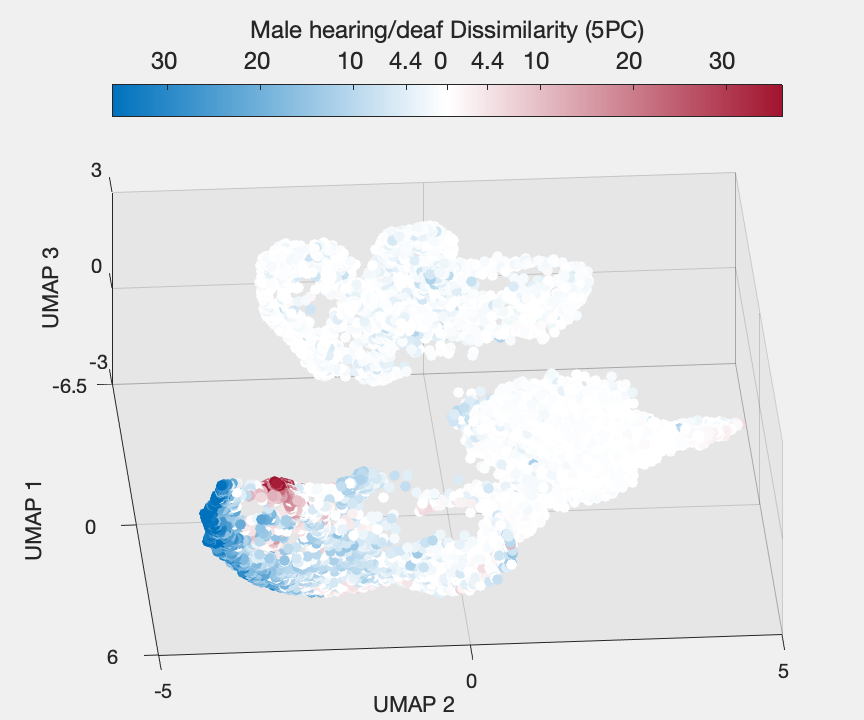

Mic_male_01 = logical(MicAudioGood01 .* contains(SexDeaf,'M'));
SexDeaf_mic = SexDeaf(MicAudioGood01);
SexDeaf_mic_males = SexDeaf(Mic_male_01 );
KSM_mic_sign = 2.*contains(SexDeaf_mic_males, 'D') -1;
NormDist = KSDistanceAll_5PC(contains(SexDeaf_mic, 'M')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'M'));
Fig13 = figure(13);
clf
set(gcf,'Visible','on')
Clustno4HM_logical = logical(contains(SexDeaf(MicAudioGood01), 'M') .* (TmicAll4~=4));
Tbl = table(MPSmicReduction4Clustering(Clustno4HM_logical,1),MPSmicReduction4Clustering(Clustno4HM_logical,2),MPSmicReduction4Clustering(Clustno4HM_logical,3),NormDist(TmicAll4(contains(SexDeaf_mic, 'M'))~=4).*KSM_mic_sign(TmicAll4(contains(SexDeaf_mic, 'M'))~=4), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
% SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30,'MarkerEdgeColor',[0.8 0.8 0.8]);
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30);
hold on
Clust4HM_logical = logical(contains(SexDeaf(MicAudioGood01), 'M') .* (TmicAll4==4));
Tbl = table(MPSmicReduction4Clustering(Clust4HM_logical,1),MPSmicReduction4Clustering(Clust4HM_logical,2),MPSmicReduction4Clustering(Clust4HM_logical,3),NormDist(TmicAll4(contains(SexDeaf_mic, 'M'))==4).*KSM_mic_sign(TmicAll4(contains(SexDeaf_mic, 'M'))==4), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30);

xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
% ColR = UCSexDeaf(1,:); % Color for Deaf males
ColR = [0.6350 0.0780 0.1840];% Color for Deaf males (dark red)
% ColL = UCSexDeaf(2,:);% Color for hearing males
ColL = [0 0.4470 0.7410];
Cmap = [(ColL(1):(1-ColL(1))/127:1)' (ColL(2):(1-ColL(2))/127:1)' (ColL(3):(1-ColL(3))/127:1)';
flip(ColR(1):(1-ColR(1))/127:1)' flip(ColR(2):(1-ColR(2))/127:1)' flip(ColR(3):(1-ColR(3))/127:1)'];
colormap(Cmap)
AxisVal = caxis();
caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
[H, E]=histcounts(NormDist, 'Normalization', 'cdf');
CLim = E(find(H>0.99,1,"first"));
caxis([-CLim CLim])
% colormap(GRAD)
cc.Label.String = 'Male hearing/deaf Dissimilarity (5PC)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;
Ticks = cc.Ticks;
MeanNull = round(mean(NullKSDistanceAll_5PC),1);
Ticks = sort([MeanNull -MeanNull Ticks]);
cc.Ticks = Ticks;
cc.TickLabels = abs(Ticks);

XLim = [-6.5 6];
set(gca, 'XLim', XLim);
YLim = [-5 5];
set(gca, 'YLim', YLim);
ZLim = [-3 3];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
set(gca, 'Color', [0.9 0.9 0.9])
Fig13.Units = 'inches';
Fig13.Position(3:4) = [6 5];
Fig13.PaperSize = [6 5];
% print(Fig13,fullfile(Path2Paper,'SupFigure3_UMAP_KSNormDistanceMales_PCA.pdf'),'-dpdf','-fillpage')
exportgraphics(Fig13,fullfile(Path2Paper,'SupFigure3_UMAP_KSNormDistanceMales_PCA.pdf'),'resolution','600')

Plot the UMAP projections with color coded the distance to the closest opposite treatment but same sex individual calls for All female bats (distance in the PCA space)

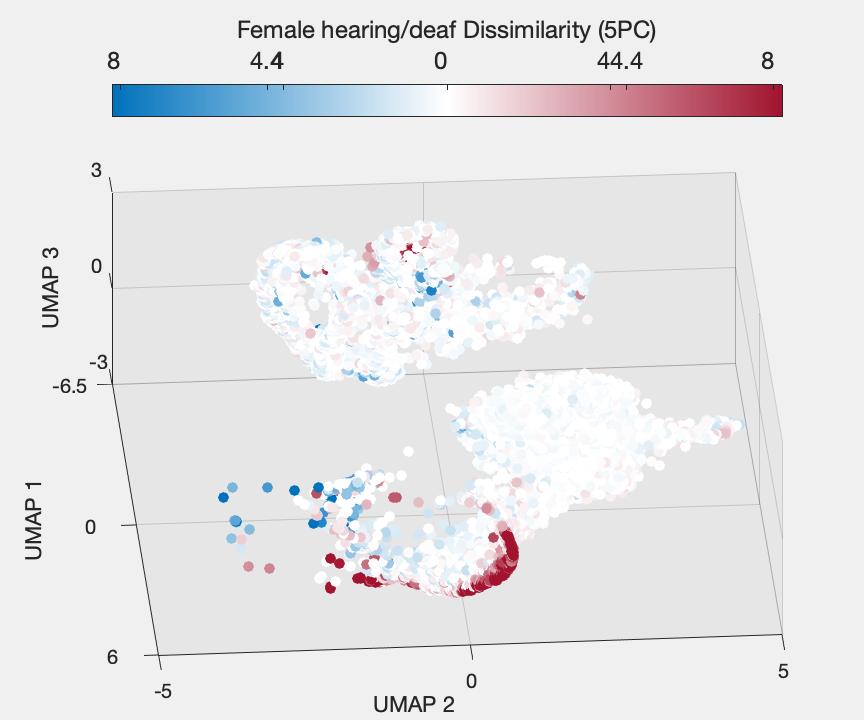

Mic_female_01 = logical(MicAudioGood01 .* contains(SexDeaf,'F'));
SexDeaf_mic = SexDeaf(MicAudioGood01);
SexDeaf_mic_females = SexDeaf(Mic_female_01 );
KSF_mic_sign = 2.*contains(SexDeaf_mic_females, 'D') -1;
NormDist = KSDistanceAll_5PC(contains(SexDeaf_mic, 'F')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'F'));
Fig14 = figure(14);
clf
set(gcf,'Visible','on')
Clustno1F_logical = logical(contains(SexDeaf(MicAudioGood01), 'F') .* (TmicAll4~=1));
Tbl = table(MPSmicReduction4Clustering(Clustno1F_logical,1),MPSmicReduction4Clustering(Clustno1F_logical,2),MPSmicReduction4Clustering(Clustno1F_logical,3),NormDist(TmicAll4(contains(SexDeaf_mic, 'F'))~=1).*KSF_mic_sign(TmicAll4(contains(SexDeaf_mic, 'F'))~=1), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30);
hold on
Clust1F_logical = logical(contains(SexDeaf(MicAudioGood01), 'F') .* (TmicAll4==1));
Tbl = table(MPSmicReduction4Clustering(Clust1F_logical,1),MPSmicReduction4Clustering(Clust1F_logical,2),MPSmicReduction4Clustering(Clust1F_logical,3),NormDist(TmicAll4(contains(SexDeaf_mic, 'F'))==1).*KSF_mic_sign(TmicAll4(contains(SexDeaf_mic, 'F'))==1), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30);
% SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30,'MarkerEdgeColor',[0.5 0.5 0.5]);

xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
% ColR = UCSexDeaf(3,:); % Color for Deaf females
ColR = [0.6350 0.0780 0.1840];
% ColL = UCSexDeaf(4,:);% Color for hearing females
ColL = [0 0.4470 0.7410];
Cmap = [(ColL(1):(1-ColL(1))/127:1)' (ColL(2):(1-ColL(2))/127:1)' (ColL(3):(1-ColL(3))/127:1)';
flip(ColR(1):(1-ColR(1))/127:1)' flip(ColR(2):(1-ColR(2))/127:1)' flip(ColR(3):(1-ColR(3))/127:1)'];
colormap(Cmap)
% AxisVal = caxis();
% caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
[H, E]=histcounts(NormDist, 'Normalization', 'cdf');
CLim = E(find(H>0.99,1,"first"));
caxis([-CLim CLim])
% colormap(GRAD)
cc.Label.String = 'Female hearing/deaf Dissimilarity (5PC)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;
Ticks = -8:4:8;
MeanNull = round(mean(NullKSDistanceAll_5PC),1);
Ticks = sort([MeanNull -MeanNull Ticks]);
cc.Ticks = Ticks;
cc.TickLabels = abs(Ticks);
set(gca, 'Color', [0.9 0.9 0.9])

XLim = [-6.5 6];
set(gca, 'XLim', XLim);
YLim = [-5 5];
set(gca, 'YLim', YLim);
ZLim = [-3 3];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])
Fig14.Units = 'inches';
Fig14.Position(3:4) = [6 5];
Fig14.PaperSize = [6 5];
exportgraphics(Fig14,fullfile(Path2Paper,'SupFigure3_UMAP_KSNormDistanceFemales_PCA.pdf'),'resolution','600')

% print(Fig14,fullfile(Path2Paper,'SupFigure3_UMAP_KSNormDistanceFemales_PCA.pdf'),'-dpdf','-fillpage')

Plot the UMAP projections with color coded the distance to the closest opposite treatment but same sex individual calls for All female bats (distance in the PCA space)

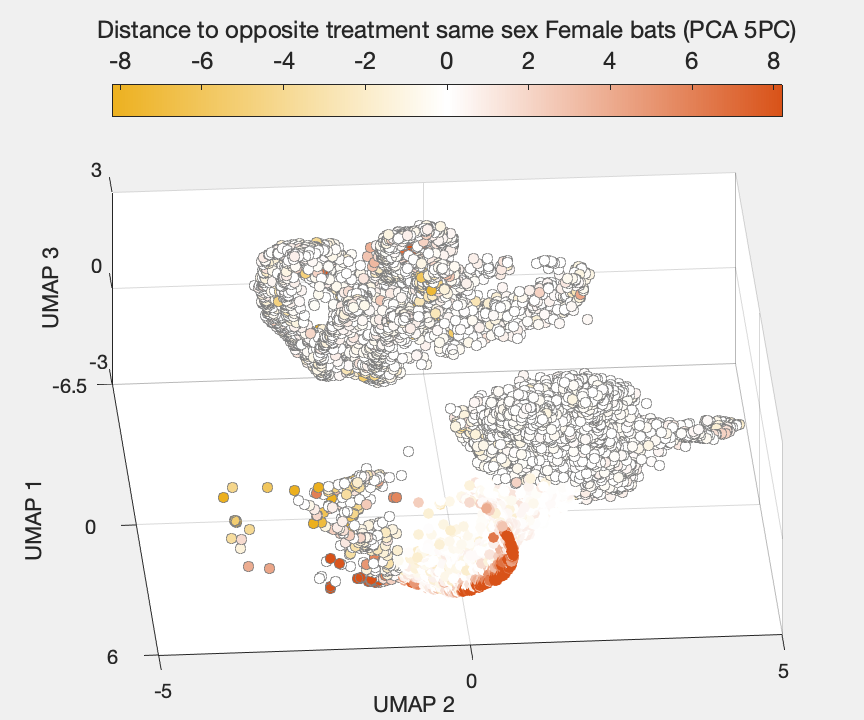

Mic_female_01 = logical(MicAudioGood01 .* contains(SexDeaf,'F'));
SexDeaf_mic = SexDeaf(MicAudioGood01);
SexDeaf_mic_females = SexDeaf(Mic_female_01 );
KSF_mic_sign = 2.*contains(SexDeaf_mic_females, 'D') -1;
NormDist = KSDistanceAll_5PC(contains(SexDeaf_mic, 'F')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'F'));
Fig14 = figure(14);
clf
set(gcf,'Visible','on')
Clustno1F_logical = logical(contains(SexDeaf(MicAudioGood01), 'F') .* (TmicAll4~=1));
Tbl = table(MPSmicReduction4Clustering(Clustno1F_logical,1),MPSmicReduction4Clustering(Clustno1F_logical,2),MPSmicReduction4Clustering(Clustno1F_logical,3),NormDist(TmicAll4(contains(SexDeaf_mic, 'F'))~=1).*KSF_mic_sign(TmicAll4(contains(SexDeaf_mic, 'F'))~=1), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30,'MarkerEdgeColor',[0.5 0.5 0.5]);
hold on
Clust1F_logical = logical(contains(SexDeaf(MicAudioGood01), 'F') .* (TmicAll4==1));
Tbl = table(MPSmicReduction4Clustering(Clust1F_logical,1),MPSmicReduction4Clustering(Clust1F_logical,2),MPSmicReduction4Clustering(Clust1F_logical,3),NormDist(TmicAll4(contains(SexDeaf_mic, 'F'))==1).*KSF_mic_sign(TmicAll4(contains(SexDeaf_mic, 'F'))==1), 'VariableNames',{'UMAP1', 'UMAP2', 'UMAP3','KSDistance'});
SC3 = scatter3(Tbl,'UMAP1', 'UMAP2','UMAP3','filled', 'ColorVariable','KSDistance', 'SizeData',30);

xlabel('UMAP 1', 'FontSize',12);
ylabel('UMAP 2', 'FontSize',12);
zlabel('UMAP 3', 'FontSize',12);
view([85.8723   54.7871])
cc=colorbar();
ColR = UCSexDeaf(3,:); % Color for Deaf females
ColL = UCSexDeaf(4,:);% Color for hearing females
Cmap = [(ColL(1):(1-ColL(1))/127:1)' (ColL(2):(1-ColL(2))/127:1)' (ColL(3):(1-ColL(3))/127:1)';
flip(ColR(1):(1-ColR(1))/127:1)' flip(ColR(2):(1-ColR(2))/127:1)' flip(ColR(3):(1-ColR(3))/127:1)'];
colormap(Cmap)
% AxisVal = caxis();
% caxis([-max(abs(AxisVal)) max(abs(AxisVal))])
[H, E]=histcounts(NormDist, 'Normalization', 'cdf');
CLim = E(find(H>0.99,1,"first"));
caxis([-CLim CLim])
% colormap(GRAD)
cc.Label.String = 'Distance to opposite treatment same sex Female bats (PCA 5PC)';
cc.FontSize = 12;
cc.Location = 'northoutside';
% cc.TickLabels = cc.Ticks/10^3;

XLim = [-6.5 6];
set(gca, 'XLim', XLim);
YLim = [-5 5];
set(gca, 'YLim', YLim);
ZLim = [-3 3];
set(gca, 'ZLim', ZLim);
set(gca, 'XTick', [XLim(1) 0 XLim(2)], 'XTickLabel', [XLim(1) 0 XLim(2)],'ZTick', [ZLim(1) 0 ZLim(2)], 'ZTickLabel', [ZLim(1) 0 ZLim(2)],'YTick', [YLim(1) 0 YLim(2)], 'YTickLabel', [YLim(1) 0 YLim(2)], 'GridColor', [0 0 0], 'FontSize',10);
hold off
view([85.723   54.7871])

Fig14.Units = 'inches';
Fig14.Position(3:4) = [6 5];
Fig14.PaperSize = [6 5];
% print(Fig14,fullfile(Path2Paper,'SupFigure3_UMAP_KSNormDistanceFemales_PCA.pdf'),'-dpdf','-fillpage')

Swarmchart of calls for each acoustic group

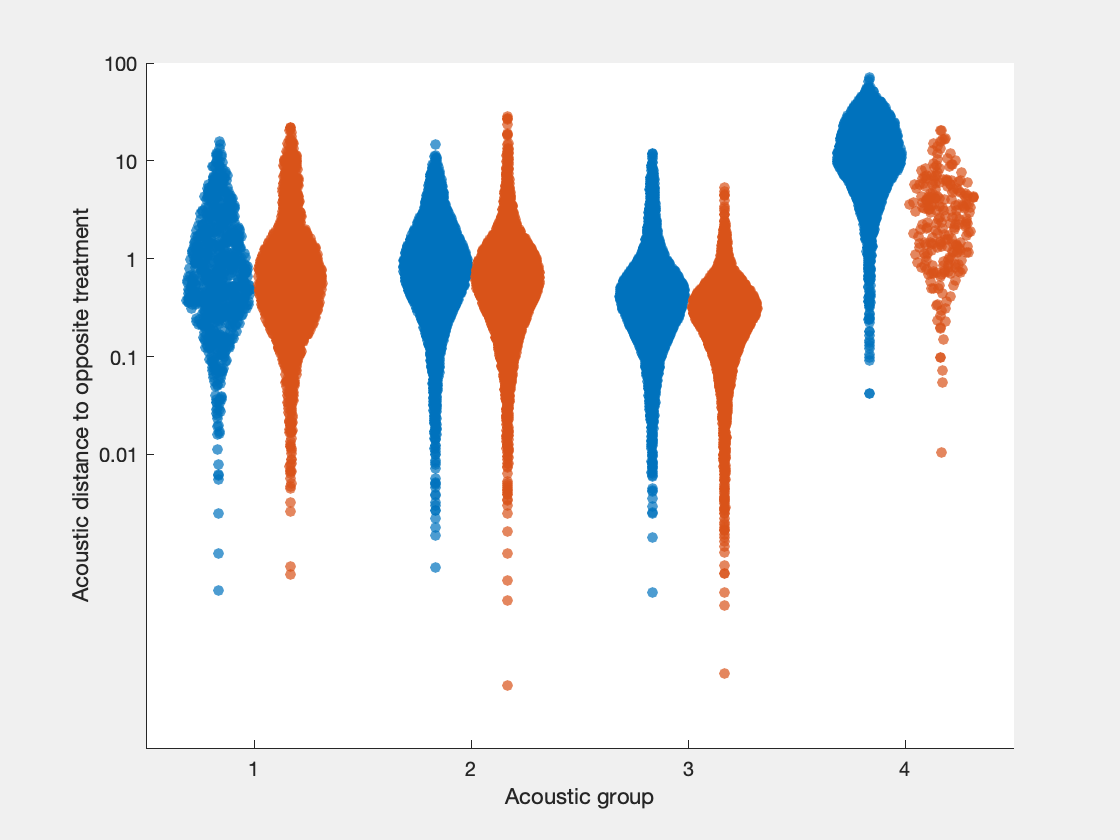

Fig16 = figure(16);
clf
set(gcf,'Visible','on')
UG = unique(TmicAll4);
XTicks = [1 2 4 5 7 8 10 11];
for gg=1:length(UG)
    Ind_M = logical(contains(SexDeaf_mic, 'M').*TmicAll4==UG(gg));
    NormDist = log10(KSDistanceAll_5PC(Ind_M) - NullKSDistanceAll_5PC(Ind_M));
    swarmchart(XTicks(gg*2-1)*ones(sum(Ind_M),1),NormDist,30,ColorCode(1,:),'o','filled','MarkerFaceAlpha',0.7,'MarkerEdgeAlpha',0.7)
    hold on
    Ind_F = logical(contains(SexDeaf_mic, 'F').*TmicAll4==UG(gg));
    NormDist = log10(KSDistanceAll_5PC(Ind_F) - NullKSDistanceAll_5PC(Ind_F));
    swarmchart(XTicks(gg*2)*ones(sum(Ind_F),1),NormDist,30,ColorCode(2,:),'o','filled','MarkerFaceAlpha',0.7,'MarkerEdgeAlpha',0.7)
end
hold off
xlabel('Acoustic group')
ylabel('Acoustic distance to opposite treatment')
xticks([1.5 4.5 7.5 10.5])
xticklabels([1 2 3 4])
yticks(-2:1:2)
yticklabels(10.^(-2:1:2))

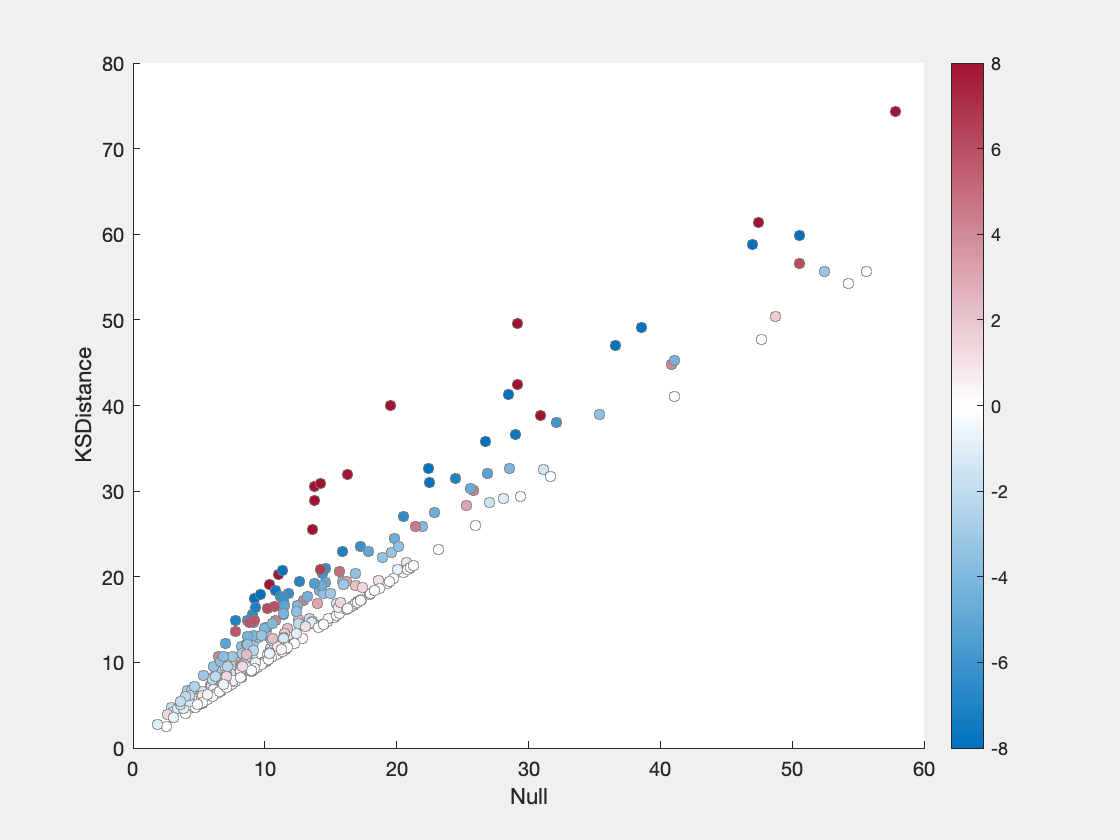

SexDeaf_mic = SexDeaf(MicAudioGood01);
SexDeaf_mic_femalesGg = SexDeaf_mic(Ind_F);
KSF_mic_sign = 2.*contains(SexDeaf_mic_femalesGg, 'D') -1;
NormDist = KSDistanceAll_5PC(Ind_F) - NullKSDistanceAll_5PC(Ind_F);

Tbl = table(NullKSDistanceAll_5PC(Ind_F),KSDistanceAll_5PC(Ind_F),NormDist.*KSF_mic_sign, 'VariableNames',{'Null', 'KSDistance', 'NormKSDistance'});
FIG17=figure(17);
clf
set(gcf,'Visible','on')
SC3 = scatter(Tbl,'Null', 'KSDistance','filled', 'ColorVariable','NormKSDistance', 'SizeData',30,'MarkerEdgeColor',[0.5 0.5 0.5]);
cc=colorbar();
% ColR = UCSexDeaf(3,:); % Color for Deaf females
ColR = [0.6350 0.0780 0.1840];
% ColL = UCSexDeaf(4,:);% Color for hearing females
ColL = [0 0.4470 0.7410];
Cmap = [(ColL(1):(1-ColL(1))/127:1)' (ColL(2):(1-ColL(2))/127:1)' (ColL(3):(1-ColL(3))/127:1)';
flip(ColR(1):(1-ColR(1))/127:1)' flip(ColR(2):(1-ColR(2))/127:1)' flip(ColR(3):(1-ColR(3))/127:1)'];
colormap(Cmap)
caxis([-8 8])

NormDist = KSDistanceAll_5PC-NullKSDistanceAll_5PC;
MeanNull = mean(NullKSDistanceAll_5PC);
StdNull = std(NullKSDistanceAll_5PC);
fprintf(1, 'Mean distance +/- 3*std to same sex individual in bat calls: %.2f +/- %.2f\n Proportion of vocalizations with KS distance more than 3STD away: %.2f%%\n',mean(NormDist),3*std(NormDist),sum(NormDist>(3*std(NormDist) + mean(NormDist)))/length(NormDist)*100)

Mean distance +/- 3*std to same sex individual in bat calls: 2.02 +/- 16.38
 Proportion of vocalizations with KS distance more than 3STD away: 2.85%


NormDistM = KSDistanceAll_5PC(contains(SexDeaf_mic, 'M')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'M'));
fprintf(1, 'Mean distance +/- 2*ste to opposite treatment in bat calls: %.2f +/- %.2f\n Proportion of vocalizations more than 2STD away: %.2f%%\n',mean(NormDistM),2*std(NormDistM)*length(NormDistM)^-0.5,sum(NormDistM>(2*std(NormDistM)*length(NormDistM)^-0.5 + mean(NormDistM)))/length(NormDistM)*100)

Mean distance +/- 2*ste to opposite treatment in bat calls: 3.40 +/- 0.12
 Proportion of vocalizations more than 2STD away: 20.70%


NormDistF = KSDistanceAll_5PC(contains(SexDeaf_mic, 'F')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'F'));
fprintf(1, 'Mean distance +/- 2*ste to opposite treatment in female calls: %.2f +/- %.2f\n Proportion of vocalizations more than 2STD away: %.2f%%\n',mean(NormDistF),2*std(NormDistF)*length(NormDistM)^-0.5,sum(NormDistF>(2*std(NormDistF)*length(NormDistM)^-0.5 + mean(NormDistF)))/length(NormDistF)*100)

Mean distance +/- 2*ste to opposite treatment in female calls: 0.64 +/- 0.03
 Proportion of vocalizations more than 2STD away: 22.10%


NormDistM = KSDistanceAll_5PC(contains(SexDeaf_mic, 'HM')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'HM'));
fprintf(1, 'Mean distance +/- 2*ste to opposite treatment in hearing male calls: %.2f +/- %.2f\n Proportion of vocalizations more than 2STD away: %.2f%%\n',mean(NormDistM),2*std(NormDistM)*length(NormDistM)^-0.5,sum(NormDistM>(2*std(NormDistM)*length(NormDistM)^-0.5 + mean(NormDistM)))/length(NormDistM)*100)

Mean distance +/- 2*ste to opposite treatment in hearing male calls: 4.33 +/- 0.16
 Proportion of vocalizations more than 2STD away: 24.57%


NormDistF = KSDistanceAll_5PC(contains(SexDeaf_mic, 'HF')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'HF'));
fprintf(1, 'Mean distance +/- 2*ste to opposite treatment in hearing female calls: %.2f +/- %.2f\n Proportion of vocalizations more than 2STD away: %.2f%%\n',mean(NormDistF),2*std(NormDistF)*length(NormDistM)^-0.5,sum(NormDistF>(2*std(NormDistF)*length(NormDistM)^-0.5 + mean(NormDistF)))/length(NormDistF)*100)

Mean distance +/- 2*ste to opposite treatment in hearing female calls: 0.52 +/- 0.02
 Proportion of vocalizations more than 2STD away: 27.95%


NormDistM = KSDistanceAll_5PC(contains(SexDeaf_mic, 'DM')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'DM'));
fprintf(1, 'Mean distance +/- 2*ste to opposite treatment in deaf male calls: %.2f +/- %.2f\n Proportion of vocalizations more than 2STD away: %.2f%%\n',mean(NormDistM),2*std(NormDistM)*length(NormDistM)^-0.5,sum(NormDistM>(2*std(NormDistM)*length(NormDistM)^-0.5 + mean(NormDistM)))/length(NormDistM)*100)

Mean distance +/- 2*ste to opposite treatment in deaf male calls: 1.52 +/- 0.17
 Proportion of vocalizations more than 2STD away: 10.68%


NormDistF = KSDistanceAll_5PC(contains(SexDeaf_mic, 'DF')) - NullKSDistanceAll_5PC(contains(SexDeaf_mic, 'DF'));
fprintf(1, 'Mean distance +/- 2*ste to opposite treatment in deaf female calls: %.2f +/- %.2f\n Proportion of vocalizations more than 2STD away: %.2f%%\n',mean(NormDistF),2*std(NormDistF)*length(NormDistM)^-0.5,sum(NormDistF>(2*std(NormDistF)*length(NormDistM)^-0.5 + mean(NormDistF)))/length(NormDistF)*100)

Mean distance +/- 2*ste to opposite treatment in deaf female calls: 0.77 +/- 0.06
 Proportion of vocalizations more than 2STD away: 18.56%


% run this calcualtion per individual
fprintf(1, 'Proportion of vocalizations with dissimilarity higher than the mean over all the data set:\n')

Proportion of vocalizations with dissimilarity higher than the mean over all the data set:


Thresh = [0.5*MeanNull; MeanNull; MeanNull + StdNull; MeanNull + 2*StdNull; MeanNull + 3*StdNull];
P_high_KSDistance = nan(length(BatName), length(Thresh));
BatID_mic = BatID(MicAudioGood01);
for bb=1:length(BatName)
    KS_local = KSDistanceAll_5PC(contains(BatID_mic, num2str(BatName(bb))));
    NullDist_local = NullKSDistanceAll_5PC(contains(BatID_mic, num2str(BatName(bb))));
    NormDistID = KS_local - NullDist_local;
    for tt=1:length(Thresh)
        P_high_KSDistance(bb,tt) = sum((NormDistID)>Thresh(tt))./length(NormDistID)*100;
    end
    fprintf(1, 'Bat %d %s %.2f%%\n', BatName(bb), BatSexDeaf{bb},P_high_KSDistance(bb,2))
end

Bat 14463 Deaf Female 3.81%
Bat 71354 Deaf Female 2.28%
Bat 71047 Deaf Female 7.26%
Bat 65696 Hearing Female 0.04%
Bat 11648 Hearing Female 2.59%
Bat 71353 Hearing Female 0.30%
Bat 71351 Deaf Male 1.21%
Bat 71043 Deaf Male 18.02%
Bat 14461 Hearing Male 27.07%
Bat 14464 Hearing Male 20.63%



FIG17=figure(17);
set(gcf,'Visible','on')
clf(FIG17)
% deaf males
shadedErrorBar(Thresh, mean(P_high_KSDistance(7:8,:)),std(P_high_KSDistance(7:8,:))*2^0.5,{'LineWidth',2, 'Color',UCSexDeaf(1,:)});
hold on
% Deaf Females
shadedErrorBar(Thresh, mean(P_high_KSDistance(1:3,:)), std(P_high_KSDistance(1:3,:))*3^-0.5, {'LineWidth',2, 'Color',UCSexDeaf(3,:)});
hold on
% Hearing Females
shadedErrorBar(Thresh, mean(P_high_KSDistance(4:6,:)),std(P_high_KSDistance(4:6,:))*3^-0.5, {'LineWidth',2, 'Color',UCSexDeaf(4,:)});
hold on
%hearing males
shadedErrorBar(Thresh, mean(P_high_KSDistance(9:10,:)),std(P_high_KSDistance(9:10,:))*2^0.5,{'LineWidth',2, 'Color',UCSexDeaf(2,:)});
hold on

% zero line
H=hline(0);
H.Color = 'k';
H.LineStyle = '--';
H.LineWidth = 2;
hold off

% Vlines
Legend = {'Mean/2' 'Mean' 'Mean+1Std' 'Mean+2Std' 'Mean+3Std'}

Legend = 1×5 cell array
    {'Mean/2'}    {'Mean'}    {'Mean+1Std'}    {'Mean+2Std'}    {'Mean+3Std'}


for tt=1:length(Thresh)
    hold on
    V=vline(Thresh(tt),'k', sprintf('%s %.1f',Legend{tt},Thresh(tt)));
    V.LineStyle = ':';
end
hold off

% legend('Deaf females', 'Hearing females','Deaf males', 'Hearing Males')
xlabel('Threshold on hearing/deaf dissimilarity')
ylabel('Proportion of Hearing/Deaf dissimilarity higher than threshold (%)')
box off
tt=2;
fprintf(1, 'Mean +/- ste Deaf Females mean thresh: %.2f +/- %.2f', mean(P_high_KSDistance(1:3,tt)), std(P_high_KSDistance(1:3,tt))*3^-0.5);

Mean +/- ste Deaf Females mean thresh: 4.45 +/- 1.47

fprintf(1, 'Mean +/- ste Hearing Females mean thresh: %.2f +/- %.2f', mean(P_high_KSDistance(4:6,tt)), std(P_high_KSDistance(4:6,tt))*3^-0.5);

Mean +/- ste Hearing Females mean thresh: 0.97 +/- 0.81

fprintf(1, 'Mean +/- ste Deaf Males mean thresh: %.2f +/- %.2f', mean(P_high_KSDistance(7:8,tt)), std(P_high_KSDistance(7:8,tt))*2^-0.5);

Mean +/- ste Deaf Males mean thresh: 9.61 +/- 8.40

fprintf(1, 'Mean +/- ste Hearing Males mean thresh: %.2f +/- %.2f', mean(P_high_KSDistance(9:10,tt)), std(P_high_KSDistance(9:10,tt))*2^-0.5);

Mean +/- ste Hearing Males mean thresh: 23.85 +/- 3.22

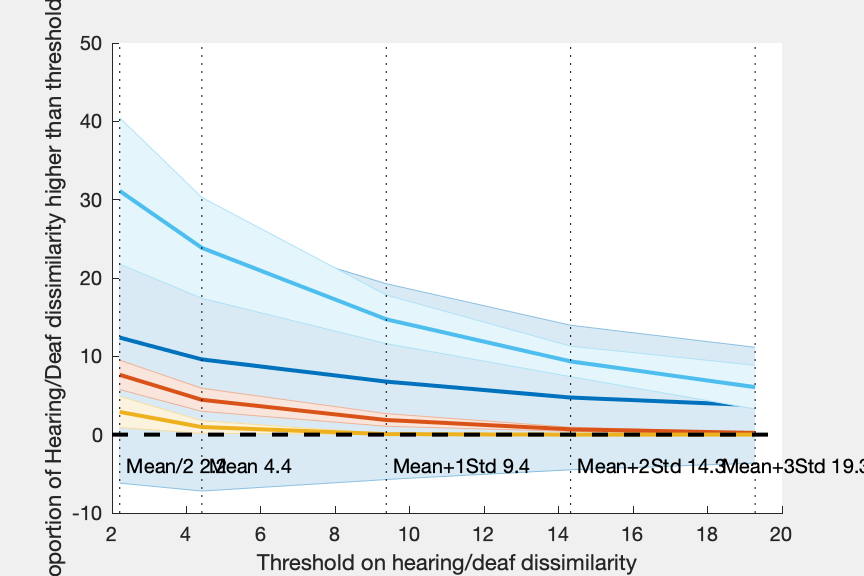

FIG17.Units = 'inches';
FIG17.Position(3:4) = [6 4];
FIG17.PaperSize = [6 4];
print(FIG17,fullfile(Path2Paper,'SupFigure_UMAP_KSDistance_ProportionLargeValues.pdf'),'-dpdf','-fillpage')

function [Colors, GRAD, MinColVal, MaxColVal, Slide]=cubehelix_ColorVal(VARcol,x, MinColVal, MaxColVal)
    % Getting VARZ ready for plotting.
    % If VARcol is always a non-null
    % integer then you can use it directly in cubehelix by specifying x=1
    % otherwise, the function first multiplies VARcol by 10^x to make sure its
    % variability is maximized after ceiling it to an integer
    if nargin<2
        x=3;% here I'm doing *1000 as an example
    end

    if nargin<3
        MinColVal=0;
    end

    if nargin<4
        MaxColVal = max(VARcol);
    end

%     if nargin<5
%         LogToggle=0;
%     end
    % Make sure you don't have nan values
    VARcol = VARcol(~isnan(VARcol));
%     if LogToggle==2
%         VARcol = log2(VARcol);
%     elseif LogToggle==10
%         VARcol = log10(VARcol);
%     end
    

    % Scale your minimum value as 0 or min Val
    Slide = 0;
    if ~MinColVal && sum(VARcol<=0)>0
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal==1
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal
        Slide = -MinColVal+ 10^(-x);
    end

    VARcol_cube = ceil((VARcol+Slide)*10^x);
    %GRAD=cubehelix(max(VARZ_cube));%Note that you can choose the values of...
    ...your gradient by doing cubehelix_view and then specifying the values in...
        ...the function, for instance: GRAD=cubehelix(max(VARZ_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -1.1, 1.5, 0.5, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
    GRAD=cubehelix(ceil((MaxColVal+Slide)*10^x),0.5, -1.5, 1, 1, [1,0]);

    NU = length(VARcol_cube); % this is the number of points you have in your plot
    Colors = nan(NU, size(GRAD,2));
    for jj=1:NU
        Colors(jj,:) = GRAD(VARcol_cube(jj),:); % for each dot you call the line in the gradient of color that correspond to the value in Z
    end
    
% figure()
%     
%     cc=colorbar();
%     colormap(GRAD)
%     set(gca, 'Color', [0.7 0.7 0.7])
%     
%     YTL = get(cc, 'YTickLabel');
%     YTL_new = ceil((MaxColVal+Slide)*10^x) .* str2double(YTL)/10^x - Slide;
%     if LogToggle==2
%         YTL_new = 2.^YTL_new;
%     elseif LogToggle==10
%         YTL_new = 10.^YTL_new;
%     end
%     YTL_new = num2str(round(YTL_new.*10^(x-1))./10^(x-1));
%     set(cc, 'YTickLabel',YTL_new)%here you correct the value of the z axis that you artificially multiplied by 10^x

end

function scatter_cubehelix(VAR, VARcol,x, MinColVal, LogToggle)
    % Getting VARZ ready for plotting.
    % Let's say you want to plot VARX VARY VARZ. If VARZ is always a non-null
    % integer then you can use it directly in cubehelix by specifying x=1
    % otherwise, the function first multiplies VARY by 10^x to make sure its
    % variability is maximized after ceiling it to an integer
    if nargin<3
        x=3;% here I'm doing *1000 as an example
    end

    if nargin<4
        MinColVal=0;
    end

    if nargin<5
        LogToggle=0;
    end
    % Make sure you don't have nan values
    VAR = VAR(~isnan(VARcol), :);
    VARcol = VARcol(~isnan(VARcol));
    if LogToggle==2
        VARcol = log2(VARcol);
    elseif LogToggle==10
        VARcol = log10(VARcol);
    end
    

    % Scale your minimum value as 0 or min Val
    Slide = 0;
    if ~MinColVal && sum(VARcol<=0)>0
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal
        Slide = -min(VARcol)+ 10^(-x);
    end

    
    
    VARcol_cube = ceil((VARcol+Slide)*10^x);
    %GRAD=cubehelix(max(VARZ_cube));%Note that you can choose the values of...
    ...your gradient by doing cubehelix_view and then specifying the values in...
        ...the function, for instance: GRAD=cubehelix(max(VARZ_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -1.1, 1.5, 0.5, [1,0]);
    GRAD=cubehelix(max(VARcol_cube),0.5, -0.8, 1.5, 1.7, [1,0]);

    NU = length(VARcol_cube); % this is the number of points you have in your plot
    Colors = nan(NU, size(GRAD,2));
    for jj=1:NU
        Colors(jj,:) = GRAD(VARcol_cube(jj),:); % for each dot you call the line in the gradient of color that correspond to the value in Z
    end
    
    figure()
    scatter3(VAR(:,1), VAR(:,2),VAR(:,3),20,Colors,'filled')
    xlabel('Dim1')
    ylabel('Dim2')
    zlabel('Dim3')
    cc=colorbar();
    colormap(GRAD)
    set(gca, 'Color', [0.7 0.7 0.7])
    
    YTL = get(cc, 'YTickLabel');
    YTL_new = max(VARcol_cube) .* str2double(YTL)/10^x - Slide;
    if LogToggle==2
        YTL_new = 2.^YTL_new;
    elseif LogToggle==10
        YTL_new = 10.^YTL_new;
    end
    YTL_new = num2str(round(YTL_new.*10^(x-1))./10^(x-1));
    set(cc, 'YTickLabel',YTL_new)%here you correct the value of the z axis that you artificially multiplied by 10^x

end
